%% Task 2: Student Performance Prediction
clear; clc; close all;

%% 1. LOAD DATA
studentData = readtable('C:\Users\Administrator\OneDrive - Habib University\Sem 4\Signals & Systems\MatLab\student_data.xlsx'); % Load Excel data
disp('First 5 rows of data:');

First 5 rows of data:


disp(head(studentData, 5)); % Show first 5 rows

    StudyHours    Attendance    AssignmentScore     Result 
    __________    __________    _______________    ________

       1.5            94              65           {'Pass'}
       2.8            36              83           {'Pass'}
       4.2            68              59           {'Fail'}
       1.2            38              64           {'Pass'}
       0.5            78              48           {'Fail'}



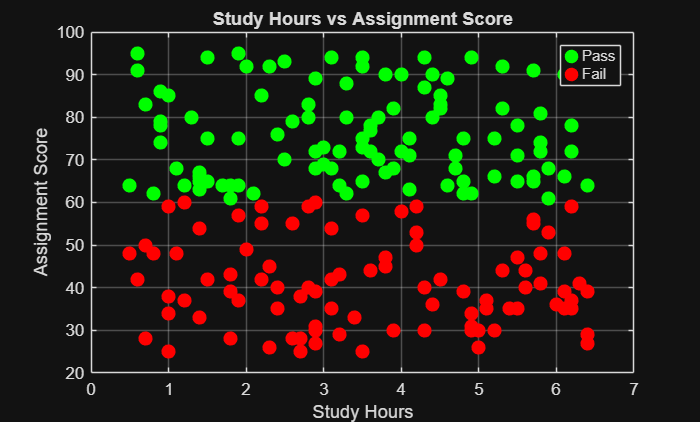


%% 2. SCATTER PLOT - Study Hours vs Assignment Score
figure(1);
passedStudents = strcmp(studentData.Result, 'Pass'); % Index of students who passed
failedStudents = strcmp(studentData.Result, 'Fail'); % Index of students who failed

plot(studentData.StudyHours(passedStudents), studentData.AssignmentScore(passedStudents), 'go', 'MarkerSize', 8, 'MarkerFaceColor', 'g'); % Plot pass
hold on;
plot(studentData.StudyHours(failedStudents), studentData.AssignmentScore(failedStudents), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r'); % Plot fail
hold off;

xlabel('Study Hours'); % X-axis label
ylabel('Assignment Score'); % Y-axis label
title('Study Hours vs Assignment Score'); % Plot title
legend('Pass', 'Fail'); % Legend
grid on; % Show grid


%% 3. PREPARE DATA
features = [studentData.StudyHours, studentData.Attendance, studentData.AssignmentScore]; % Features for model
labels = studentData.Result; % Labels

% Normalize features between 0 and 1
featuresNorm = (features - min(features)) ./ (max(features) - min(features));

%% 4. SPLIT DATA (80% train, 20% test)
rng(42); % For reproducibility
numStudents = size(featuresNorm, 1); % Total number of students
shuffledIndices = randperm(numStudents); % Shuffle indices
trainCount = round(0.8 * numStudents); % 80% for training

trainFeatures = featuresNorm(shuffledIndices(1:trainCount), :); % Training features
trainLabels = labels(shuffledIndices(1:trainCount)); % Training labels
testFeatures = featuresNorm(shuffledIndices(trainCount+1:end), :); % Test features
testLabels = labels(shuffledIndices(trainCount+1:end)); % Test labels

%% 5. TRAIN AND TEST MODELS

% Model 1: Logistic Regression
logisticModel = fitclinear(trainFeatures, trainLabels, 'Learner', 'logistic'); % Train model
predLogistic = predict(logisticModel, testFeatures); % Predict test labels
accuracyLogistic = mean(strcmp(predLogistic, testLabels)) * 100; % Accuracy
fprintf('Logistic Regression Accuracy: %.1f%%\n', accuracyLogistic);

Logistic Regression Accuracy: 92.5%


confMatrixLogistic = confusionmat(testLabels, predLogistic); % Confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMatrixLogistic);

    19     0
     3    18




% Model 2: Decision Tree
treeModel = fitctree(trainFeatures, trainLabels); % Train tree
predTree = predict(treeModel, testFeatures); % Predict
accuracyTree = mean(strcmp(predTree, testLabels)) * 100; % Accuracy
fprintf('Decision Tree Accuracy: %.1f%%\n', accuracyTree);

Decision Tree Accuracy: 100.0%


confMatrixTree = confusionmat(testLabels, predTree); % Confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMatrixTree);

    19     0
     0    21




% Model 3: Random Forest
forestModel = TreeBagger(30, trainFeatures, trainLabels, 'Method', 'classification'); % Train forest
predForest = predict(forestModel, testFeatures); % Predict
predForest = strtrim(predForest); % Remove extra spaces
accuracyForest = mean(strcmp(predForest, testLabels)) * 100; % Accuracy
fprintf('Random Forest Accuracy: %.1f%%\n', accuracyForest);

Random Forest Accuracy: 100.0%


confMatrixForest = confusionmat(testLabels, predForest); % Confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMatrixForest);

    19     0
     0    21




% Model 4: SVM
svmModel = fitcsvm(trainFeatures, trainLabels); % Train SVM
predSVM = predict(svmModel, testFeatures); % Predict
accuracySVM = mean(strcmp(predSVM, testLabels)) * 100; % Accuracy
fprintf('SVM Accuracy: %.1f%%\n', accuracySVM);

SVM Accuracy: 92.5%


confMatrixSVM = confusionmat(testLabels, predSVM); % Confusion matrix
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMatrixSVM);

    19     0
     3    18




% Find best model
[bestAccuracy, bestIndex] = max([accuracyLogistic, accuracyTree, accuracyForest, accuracySVM]);
modelNames = {'Logistic Regression', 'Decision Tree', 'Random Forest', 'SVM'};
fprintf('\nBest Model: %s with %.1f%% accuracy\n', modelNames{bestIndex}, bestAccuracy);


Best Model: Decision Tree with 100.0% accuracy



%% 7. TEST WITH A NEW STUDENT
fprintf('\n=== TEST NEW STUDENT ===\n');


=== TEST NEW STUDENT ===


newStudent = [5, 85, 78]; % StudyHours, Attendance, AssignmentScore
newStudentNorm = (newStudent - min(features)) ./ (max(features) - min(features)); % Normalize

% Predict using best model
if bestIndex == 1
    prediction = predict(logisticModel, newStudentNorm);
elseif bestIndex == 2
    prediction = predict(treeModel, newStudentNorm);
elseif bestIndex == 3
    prediction = predict(forestModel, newStudentNorm);
    prediction = strtrim(prediction);
else
    prediction = predict(svmModel, newStudentNorm);
end

fprintf('New Student: Hours=%d, Attendance=%d%%, Score=%d\n', newStudent(1), newStudent(2), newStudent(3));

New Student: Hours=5, Attendance=85%, Score=78


fprintf('Predicted Result: %s\n', prediction{1});

Predicted Result: Pass
